**Clear Section**

clear
clc
close all

**Transmitter**

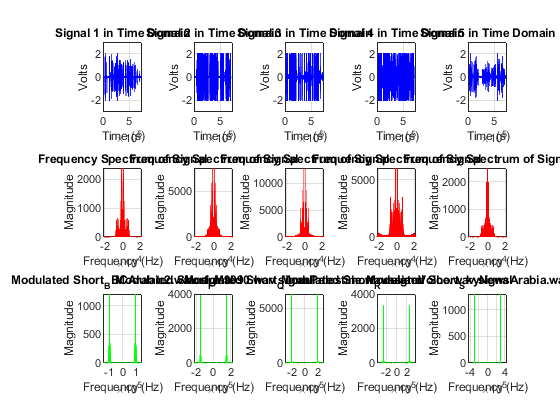

filename = ["Short_BBCArabic2.wav", "Short_FM9090.wav", "Short_QuranPalestine.wav", "Short_RussianVoice.wav", "Short_SkyNewsArabia.wav"];                      % names of audio files
sum_signals = 0;
for i = 1 : 5
    %%%%%%%%%% Reading monophonic audio signals into MATLAB %%%%%%%%%%
    [auido_signal, Fs] = audioread(filename(i));                            % read audio and getting sample frequency
    auido_signal = sum(auido_signal.');                                     % converte from stereo to mono sound
    auido_signal = auido_signal';                                           % converte from stereo to mono sound
    max_audio_length = 740544;                                              % max audio length
    auido_signal(end + max_audio_length - length(auido_signal) , 1) = 0;    % adding zeros to short audios
    
    subplot(3,5,i)                                                          % Create axes in tiled positions
    plot(auido_signal, 'b');
    title("Signal " + i + " in Time Domain")
    xlabel("Time (s)")
    ylabel("Volts")
    grid on 
    ylim([-3 3])

    %%%%%%%%%% FFT of Audio signal %%%%%%%%%%
    AUDIO_SIGNAL = fft(auido_signal, length(auido_signal));
    f_Y = (-length(AUDIO_SIGNAL)/2:1:length(AUDIO_SIGNAL)/2-1)';
    subplot(3,5,5 + i)
    plot(f_Y*(Fs/length(AUDIO_SIGNAL)), fftshift(abs(AUDIO_SIGNAL)), 'r')
    title("Frequency Spectrum of Signal")
    xlabel("Frequency (Hz)")
    ylabel("Magnitude")
    grid on 
    
    auido_signal = interp(auido_signal, 15);
    %%%%%%%%%% Local Oscillator (Carrier) %%%%%%%%%%
    n = (i-1);
    delta_f = 50000;                 
    f_o = 100000;                    
    fn = f_o + n*delta_f;            
    Fs_carrier = 15*Fs;              
    t = (1:1:length(auido_signal))'; 
    carrier_signal = cos(2*pi*fn*t*(1/(15*Fs)))/15;

    %%%%%%%%%% AM-SC modulation %%%%%%%%%%
    modulating_signal = interp(auido_signal, 1);
    carrier_signal(end + length(modulating_signal) - length(carrier_signal), 1) = 0;
    modulated_signal = carrier_signal.*modulating_signal; 
    MODULATED_SIGNAL = fftshift(fft(modulated_signal));
    
    %%%%%%%%%% Addition of the modulated signals %%%%%%%%%%
    sum_signals = sum_signals + modulated_signal;

    f_MODULATED_SIGNAL = (-length(MODULATED_SIGNAL)/2:1:length(MODULATED_SIGNAL)/2-1)';
    subplot(3,5,10 + i)
    plot(f_MODULATED_SIGNAL*Fs_carrier/length(MODULATED_SIGNAL),abs(MODULATED_SIGNAL), 'g')
    title("Modulated " + filename(i) + " signal")
    xlabel("Frequency (Hz)")
    ylabel("Magnitude")
    grid on 
    xlim([-1.5*fn 1.5*fn])
end

plot  transmitted signal

SUM_SIGNALS = fftshift(fft(sum_signals));
f_MODULATED_SIGNAL = (-length(SUM_SIGNALS)/2:1:length(SUM_SIGNALS)/2-1)';
figure('Name', 'RF stage')
subplot(2,1,1)
plot(f_MODULATED_SIGNAL*Fs_carrier/length(SUM_SIGNALS),abs(SUM_SIGNALS), 'g')
title("Transmitted Signals")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
grid on 

The RF stage

fprintf("Choose one of these channels:\n");

Choose one of these channels:


fprintf("1. Short_BBCArabic2\n");

1. Short_BBCArabic2


fprintf("2. Short_FM9090\n");

2. Short_FM9090


fprintf("3. Short_QuranPalestine\n");

3. Short_QuranPalestine


fprintf("4. Short_RussianVoice\n");

4. Short_RussianVoice


fprintf("5. Short_SkyNewsArabia\n");

5. Short_SkyNewsArabia


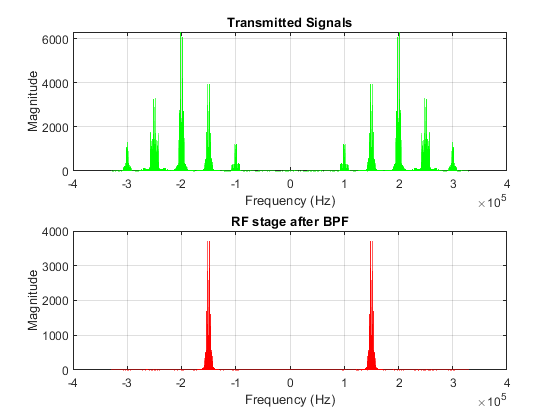

choose_signal = input("Choose: "); 
signal_number = 0.5*choose_signal+0.5;
BW = 30000;
A_stop1 = 60;                           % Attenuation in the first stopband = 60 dB
F_stop1 = signal_number*100000-BW;      % Edge of the stopband = 8400 Hz
F_pass1 = signal_number*100000-BW/2;    % Edge of the passband = 10800 Hz
F_pass2 = signal_number*100000+BW/2;    % Closing edge of the passband = 15600 Hz
F_stop2 = signal_number*100000+BW;      % Edge of the second stopband = 18000 Hz
A_stop2 = 60;                           % Attenuation in the second stopband = 60 dB
A_pass = 1;                             % Amount of ripple allowed in the passband = 1 dB

band_pass_filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, 15*Fs);
band_pass_filter = design(band_pass_filter, 'equiripple');
sum_signals_BPF  = filter(band_pass_filter, sum_signals);
SUM_SIGNALS_BPF  = fftshift(fft(sum_signals_BPF));
f_MODULATED_SIGNAL = (-length(SUM_SIGNALS_BPF)/2:1:length(SUM_SIGNALS_BPF)/2-1)';
subplot(2,1,2)
plot(f_MODULATED_SIGNAL*Fs_carrier/length(SUM_SIGNALS_BPF), abs(SUM_SIGNALS_BPF), 'r')
title("RF stage after BPF")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
grid on

The IF stage

fc = signal_number*100000;       % [100, 150, 200, 250, 300] KHz
IF = 25000;                      % If frequency 25 KHz
f_carrier = fc + IF;             % carrier frequency
Fs_carrier = 15*Fs;              % 15*Fs;
t = (1:1:length(sum_signals_BPF))';
carrier_signal_IF = cos(2*pi*f_carrier*t*(1/(15*Fs)));
carrier_signal_IF(end + length(sum_signals_BPF) - length(carrier_signal_IF), 1) = 0;
IF_received_signal = sum_signals_BPF.*carrier_signal_IF;
IF_RECEIVED_SIGNAL = fftshift(fft(IF_received_signal));
f_RECEIVED_SIGNAL = (-length(IF_RECEIVED_SIGNAL)/2:1:length(IF_RECEIVED_SIGNAL)/2-1)';
figure('Name', 'If stage')
subplot(2,1,1)
plot(f_RECEIVED_SIGNAL*Fs_carrier/length(IF_RECEIVED_SIGNAL),abs(IF_RECEIVED_SIGNAL), 'g')
title("IF stage of " + filename(choose_signal) + " channel")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
grid on 

IF stage with BPF

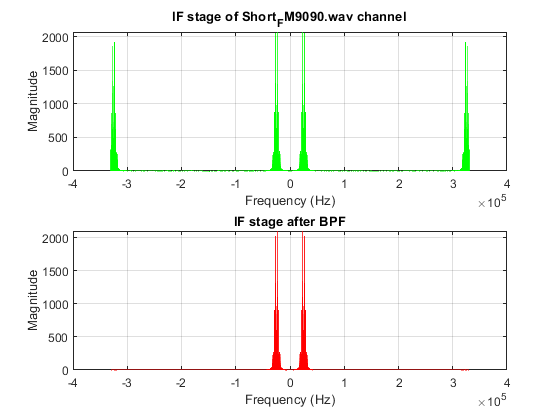

BW = 30000;
A_stop1 = 60;                           % Attenuation in the first stopband = 60 dB
F_stop1 = BW - IF;                      % Edge of the stopband = 8400 Hz
F_pass1 = IF-BW/2;                      % Edge of the passband = 10800 Hz
F_pass2 = IF+BW/2;                      % Closing edge of the passband = 15600 Hz
F_stop2 = BW + IF;                      % Edge of the second stopband = 18000 Hz
A_stop2 = 60;                           % Attenuation in the second stopband = 60 dB
A_pass = 1;                             % Amount of ripple allowed in the passband = 1 dB

band_pass_filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, 15*Fs);
band_pass_filter = design(band_pass_filter, 'equiripple');
IF_received_signal_BPF  = filter(band_pass_filter, IF_received_signal);
IF_RECEIVED_SIGNAL_BPF  = fftshift(fft(IF_received_signal_BPF));
f_RECEIVED_SIGNAL_BPF = (-length(IF_RECEIVED_SIGNAL_BPF)/2:1:length(IF_RECEIVED_SIGNAL_BPF)/2-1)';
subplot(2,1,2)
plot(f_RECEIVED_SIGNAL_BPF*Fs_carrier/length(IF_RECEIVED_SIGNAL_BPF), abs(IF_RECEIVED_SIGNAL_BPF), 'r')
title("IF stage after BPF")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
grid on

The Base Band Demodulation

fc = signal_number*100000;       % [100, 150, 200, 250, 300] KHz
Base_Band_freq = 25000;          % If frequency 25 KHz
f_carrier = Base_Band_freq;      % carrier frequency
Fs_carrier = 15*Fs;              % 15*Fs;
t = (1:1:length(IF_received_signal_BPF))';
carrier_signal_Base_Band = cos(2*pi*f_carrier*t*(1/(15*Fs)));
carrier_signal_Base_Band(end + length(sum_signals_BPF) - length(carrier_signal_Base_Band), 1) = 0;
Base_Band_received_signal = IF_received_signal_BPF.*carrier_signal_Base_Band;
BASE_BAND_RECEIVED_SIGNAL = fftshift(fft(Base_Band_received_signal));
f_RECEIVED_SIGNAL_BASE_BAND = (-length(BASE_BAND_RECEIVED_SIGNAL)/2:1:length(BASE_BAND_RECEIVED_SIGNAL)/2-1)';
figure('Name', 'Base Band stage')
subplot(2,1,1)
plot(f_RECEIVED_SIGNAL_BASE_BAND*Fs_carrier/length(BASE_BAND_RECEIVED_SIGNAL),abs(BASE_BAND_RECEIVED_SIGNAL), 'g')
title("Base Band stage of " + filename(choose_signal) + " channel")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
grid on 

The Base Band Demodulation with LPF

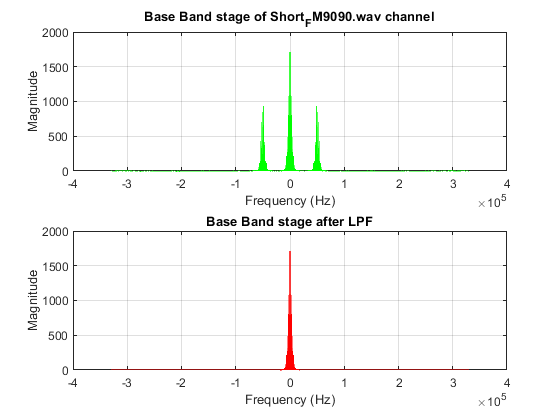

BW = 30000;
F_stop = BW/2+20000;              % Edge of the stopband = 8400 Hz
F_pass = BW/2;                    % Edge of the passband = 10800 Hz
A_stop = 60;                      % Attenuation in the second stopband = 60 dB
A_pass = 1;                       % Amount of ripple allowed in the passband = 1 dB

low_pass_filter = fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, 15*Fs);
low_pass_filter = design(low_pass_filter, 'butter');
Base_Band_received_signal_LPF  = filter(low_pass_filter, Base_Band_received_signal);
BASE_BAND_RECEIVED_SIGNAL_LPF  = fftshift(fft(Base_Band_received_signal_LPF));
f_RECEIVED_SIGNAL_LPF = (-length(BASE_BAND_RECEIVED_SIGNAL_LPF)/2:1:length(BASE_BAND_RECEIVED_SIGNAL_LPF)/2-1)';
subplot(2,1,2)
plot(f_RECEIVED_SIGNAL_LPF*Fs_carrier/length(BASE_BAND_RECEIVED_SIGNAL_LPF), abs(BASE_BAND_RECEIVED_SIGNAL_LPF), 'r')
title("Base Band stage after LPF")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
grid on

Base_Band_received_signal_LPF = 4*resample(Base_Band_received_signal_LPF, 1, 15);
sound(Base_Band_received_signal_LPF, Fs)